# Industrial diagnostics of compressor connection rod defects

Industrial production of compressors suffers from problems during the imprinting operation where a connection rod is connected with a compressor head. Irregular imprinting can cause damage or crack of the connection rod which results in a damaged compressor. Such compressors should be eliminated from the production line but defects of this type are difficult to detect.

This example demonstrates an application of a multilayer perceptron for industrial diagnostics of cracks and overload defects by using the measurement of the imprinting force.

The dimensionality of input data (measured imprinting force) is reduced by resampling, and the multilayer perceptron is trained on these data to detect cracks and overload defects.

2022 © Primož Potočnik ([University of Ljubljana](https://www.uni-lj.si), [Faculty of Mechanical Engineering](https://www.fs.uni-lj.si))

## Connection rod failures  

The photos show the compressor head where the connection rod can be seen, and the crack on the connection rod.

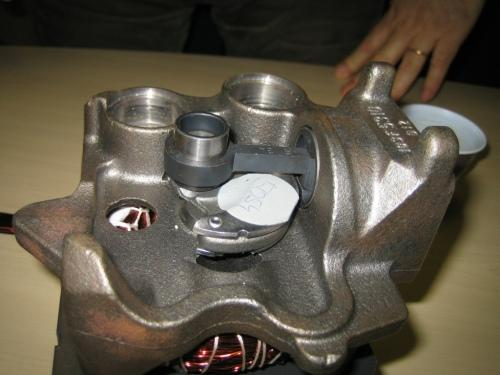 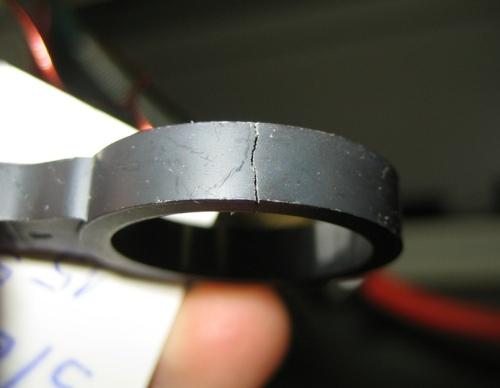

## Load data

close all, clear all, clc, format compact

% industrial data
load nndata.mat
whos

  Name            Size               Bytes  Class     Attributes

  classes         1x3                  342  cell                
  forces       2000x100            1600000  double              
  labels       2000x1                16000  double              



The data were originally acquired on the industrial line of compressors and collected in cooperation with the Laboratory of Synergetics (Faculty of Mechanical Engineering, University of Ljubljana, Slovenia).

The data comprise of 2000 samples of measured forces and corresponding labels, denoting the following classess:

- 'OK'

- 'Overload'

- 'Crack'

## Plot data

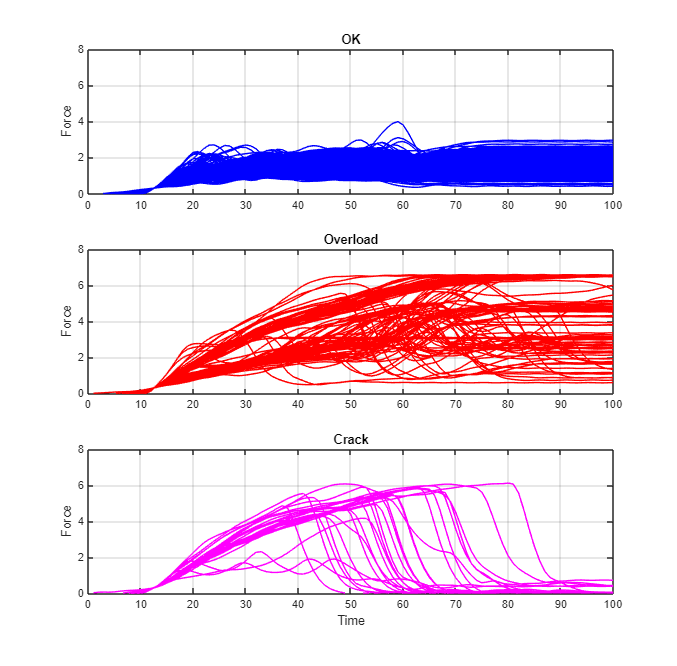

figure('Units','Normalized','OuterPosition',[0,0,.4,.7]); % resize figure

% show data for class 1: OK
subplot 311
plot(forces(labels==1,:)','b')
grid on
ylim([0 8])
ylabel('Force')
title(classes{1})

% show data for class 2: Overload
subplot 312
plot(forces(labels==2,:)','r')
grid on
ylim([0 8])
ylabel('Force')
title(classes{2})

% show data for class 3: Crack
subplot 313
plot(forces(labels==3,:)','m')
grid on
ylim([0 8])
xlabel('Time')
ylabel('Force')
title(classes{3})

## Prepare inputs: data reduction by resampling

% include only every step-th data
step = 10;

% resample data
forces2 = forces(:,1:step:size(forces,2));

% display dimensions of original (force) and resampled data (force2)
whos force*

  Name            Size               Bytes  Class     Attributes

  forces       2000x100            1600000  double              
  forces2      2000x10              160000  double              



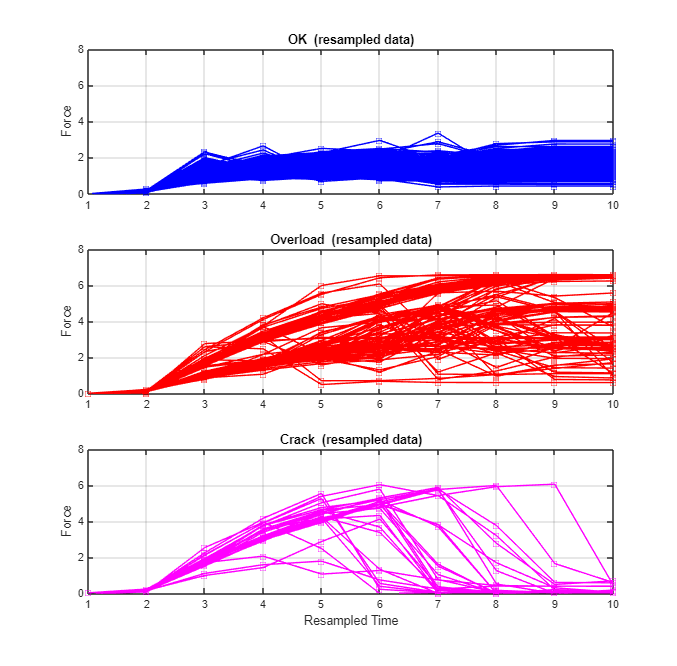

% show resampled data for class 1: OK
figure('Units','Normalized','OuterPosition',[0,0,.4,.7]); % resize figure
subplot 311
plot(forces2(labels==1,:)','bs-')
grid on
ylim([0 8])
ylabel('Force')
title([classes{1} '  (resampled data)'])

% show resampled data for class 2: Overload
subplot 312
plot(forces2(labels==2,:)','rs-')
grid on
ylim([0 8])
ylabel('Force')
title([classes{2} '  (resampled data)'])

% show resampled data for class 3: Crack
subplot 313
plot(forces2(labels==3,:)','ms-')
grid on
ylim([0 8])
xlabel('Resampled Time')
ylabel('Force')
title([classes{3} '  (resampled data)'])

Plot resampled data

## Define output coding: 0=OK, 1=Defect

To simplify the task, the data from 3 classes ('OK', 'Overload', 'Crack') are summarized into only 2 classes: 'OK' and 'Defect'.

% binary output coding 0/1
labels_defect = double(labels > 1);

## Create and train a multilayer perceptron

Built-in MATLAB function 'feedforwardnet' is used to construct the multilayer perceptron.

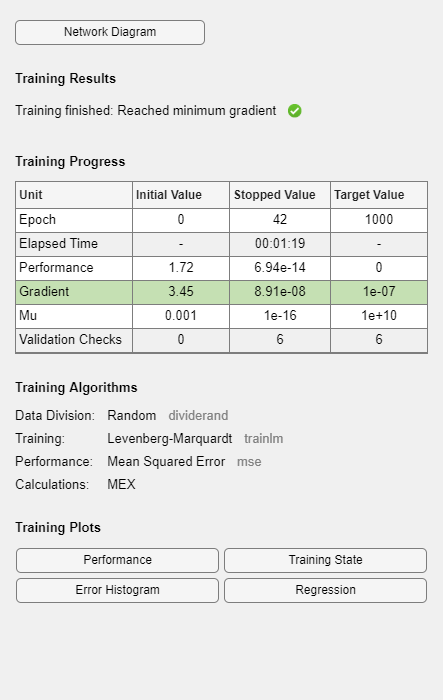

num_hidden_layer =6; % number of neurons in the hidden layer

% create a neural network
net = feedforwardnet(num_hidden_layer);

% training parameters
net.divideParam.trainRatio = 0.70; % training set [%]
net.divideParam.valRatio   = 0.15; % validation set [%]
net.divideParam.testRatio  = 0.15; % test set [%]

% train a neural network
[net,tr,Y,E] = train(net,forces2',labels_defect');

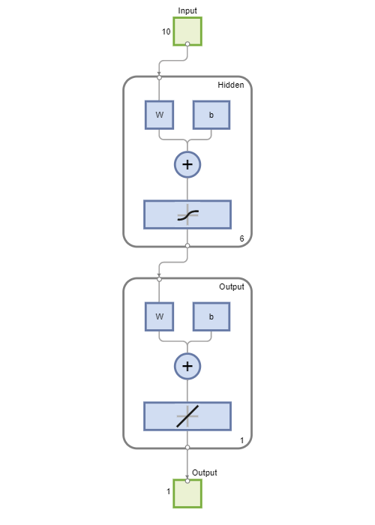

% view net
view(net);

## Evaluate network performance

Evaluate network performance by calculating the classification accuracy. 

% digitize network response
threshold = 0.5;
P = double(Y > threshold)';

% calculate classification accuracy
classification_accuracy = length(find(P==labels_defect))/length(labels_defect)

classification_accuracy = 0.9990

## Application of a trained classifier

A trained neural network classifier is applied to random sample (chosen by sample_index), true quality and predicted quality are displayed, and the chosen sample is shown in the context of all samples. The network response is denoted as CORRECT or FALSE.

% pick a sample
sample_index = 1652; 
 

% collect sample
sample = forces2(sample_index,:);
% true quality
true_quality = labels_defect(sample_index)

true_quality = 1

% predict quality
q = net(sample');
% digitize network response
predicted_quality = double(q > threshold)'

predicted_quality = 1

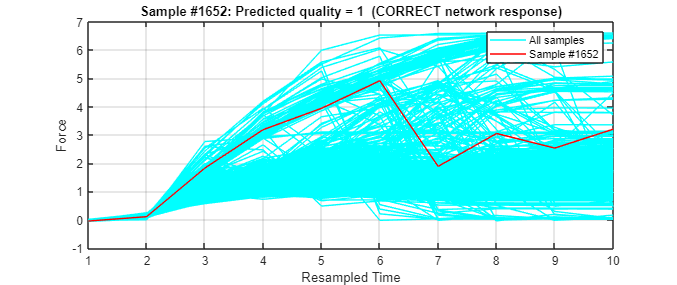

% plot
figure('Units','Normalized','OuterPosition',[0,0,.4,.3]); % resize figure
f1 = plot(forces2','c');
grid on, hold on
color = {'b','r'}; % colors for samples classified as OK (blue) or Faults (red)
f2 = plot(sample,'color',color{predicted_quality+1});
xlabel('Resampled Time')
ylabel('Force')
legend([f1(1) f2],'All samples',sprintf('Sample #%d',sample_index))

% comment network respons
if predicted_quality == true_quality
  title(sprintf('Sample #%d: Predicted quality = %d  (CORRECT network response)',sample_index,predicted_quality))
else
  title(sprintf('Sample #%d: Predicted quality = %d  (FALSE network response)',sample_index,predicted_quality))
end

% close all windows
close all force

## PowerPoint presentation

[NN4a_Backpropagation.pptx](matlab:open('./NN4a_Backpropagation.pptx'))